data = table2array(readtable('../../data/data1/CHID46.csv'));
dpi = data(:,1);
y = data(:,2);
num_pat = 1;

h = 0.01;
ti = 0:h:dpi(end); 
init = [10^4 0 10^-3];


x0 = [0.409*10^-6, 0.233*10^-6, 0.249, 0.775, 14.5*10^3, 0.03, 7];
disp(J(x0, ti, init, h, dpi, y));

    0.0079




xx0 = log10(x0);
disp(J2(xx0, ti, init, h, dpi, y));

    0.0079



    0.0079



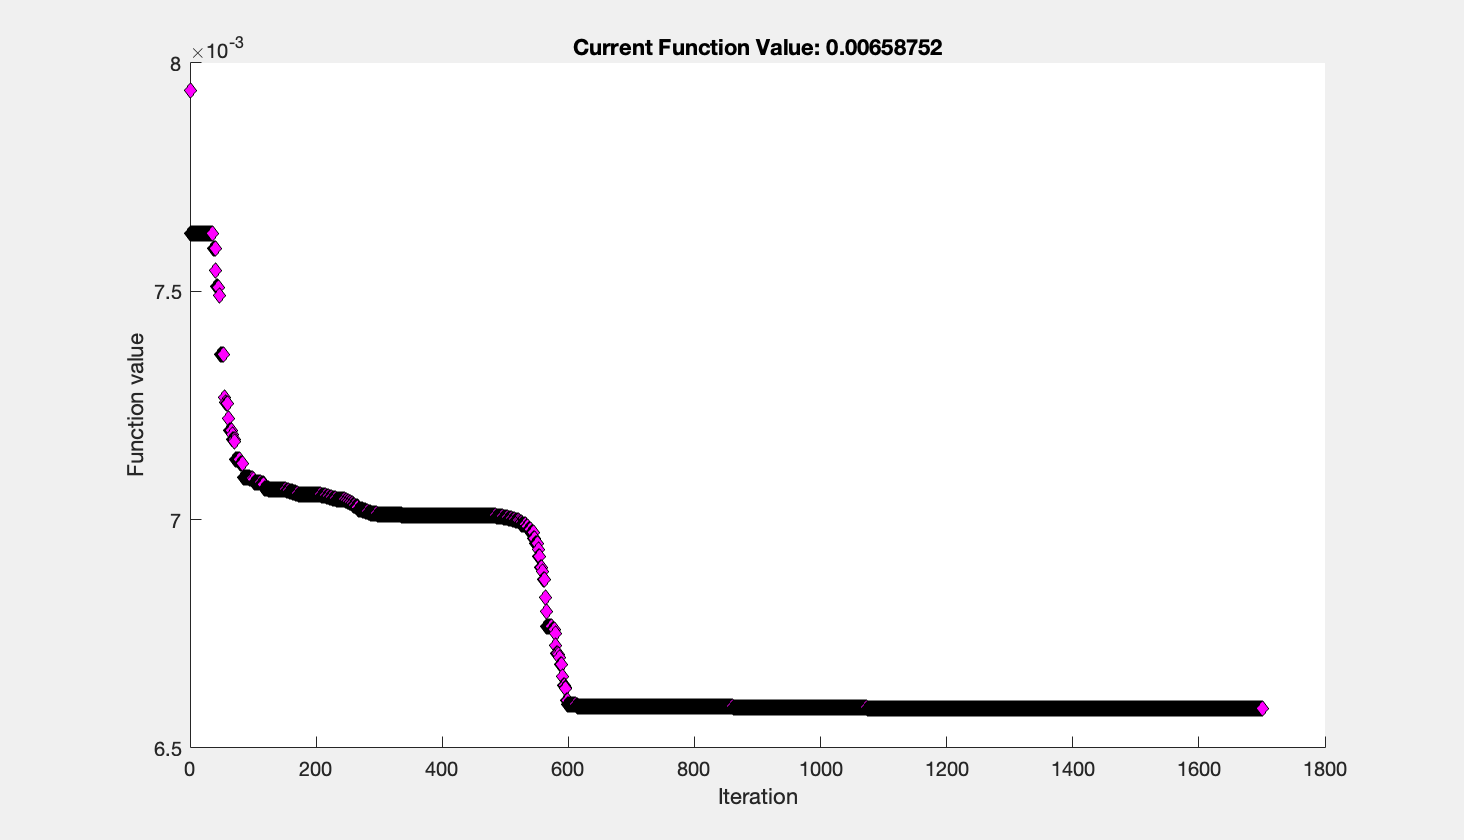

[bp2, fval2] = best_param2(xx0,dpi,y,ti,init,h) ;

fval2

fval2 = 0.0066

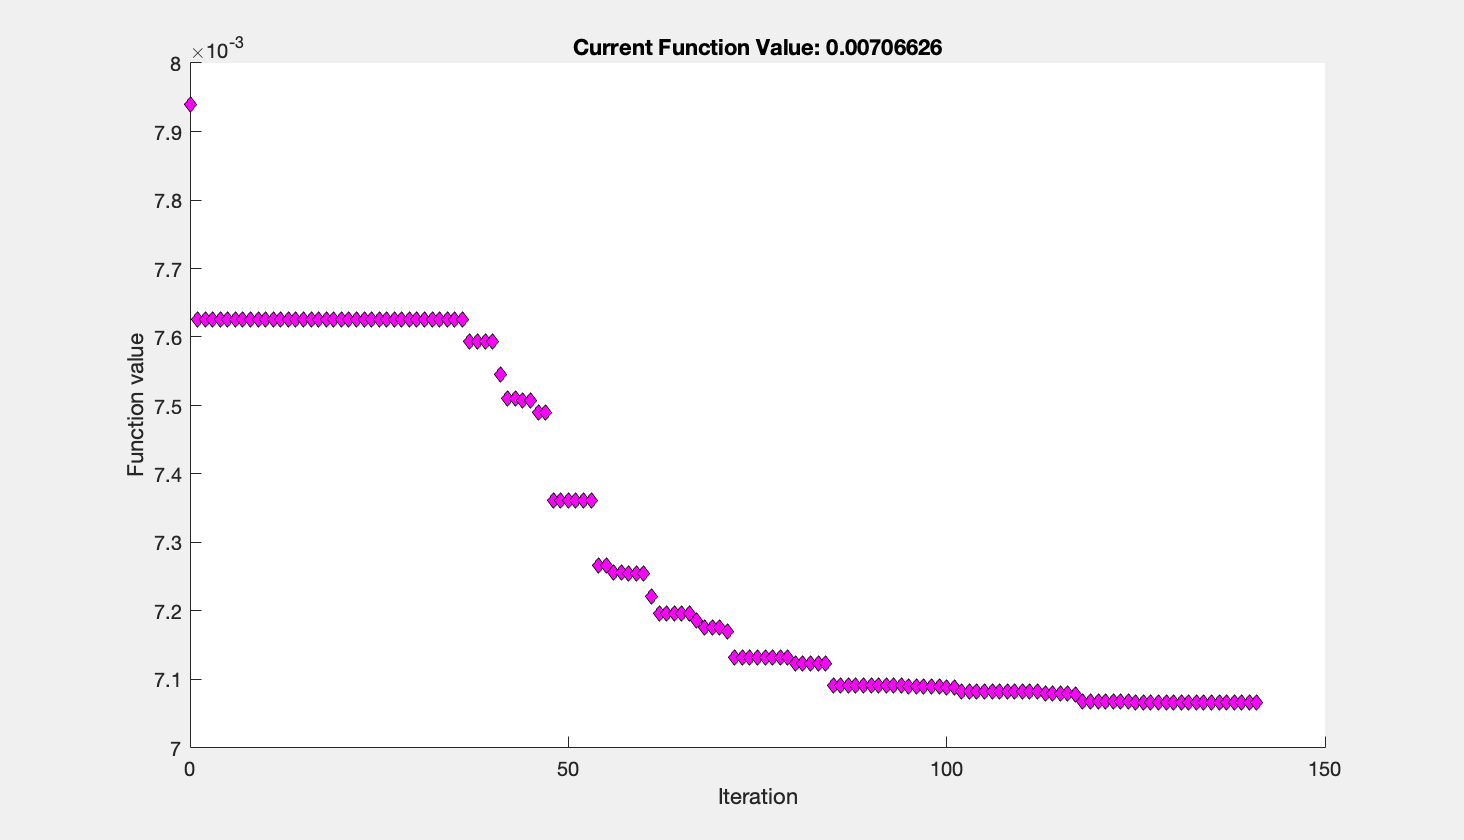


% [bp, fval] = best_param(x0,dpi,y,ti,init,h) ;
% fval


[bp2, fval2] = best_param2(xx0,dpi,y,ti,init,h) ;

    0.0056



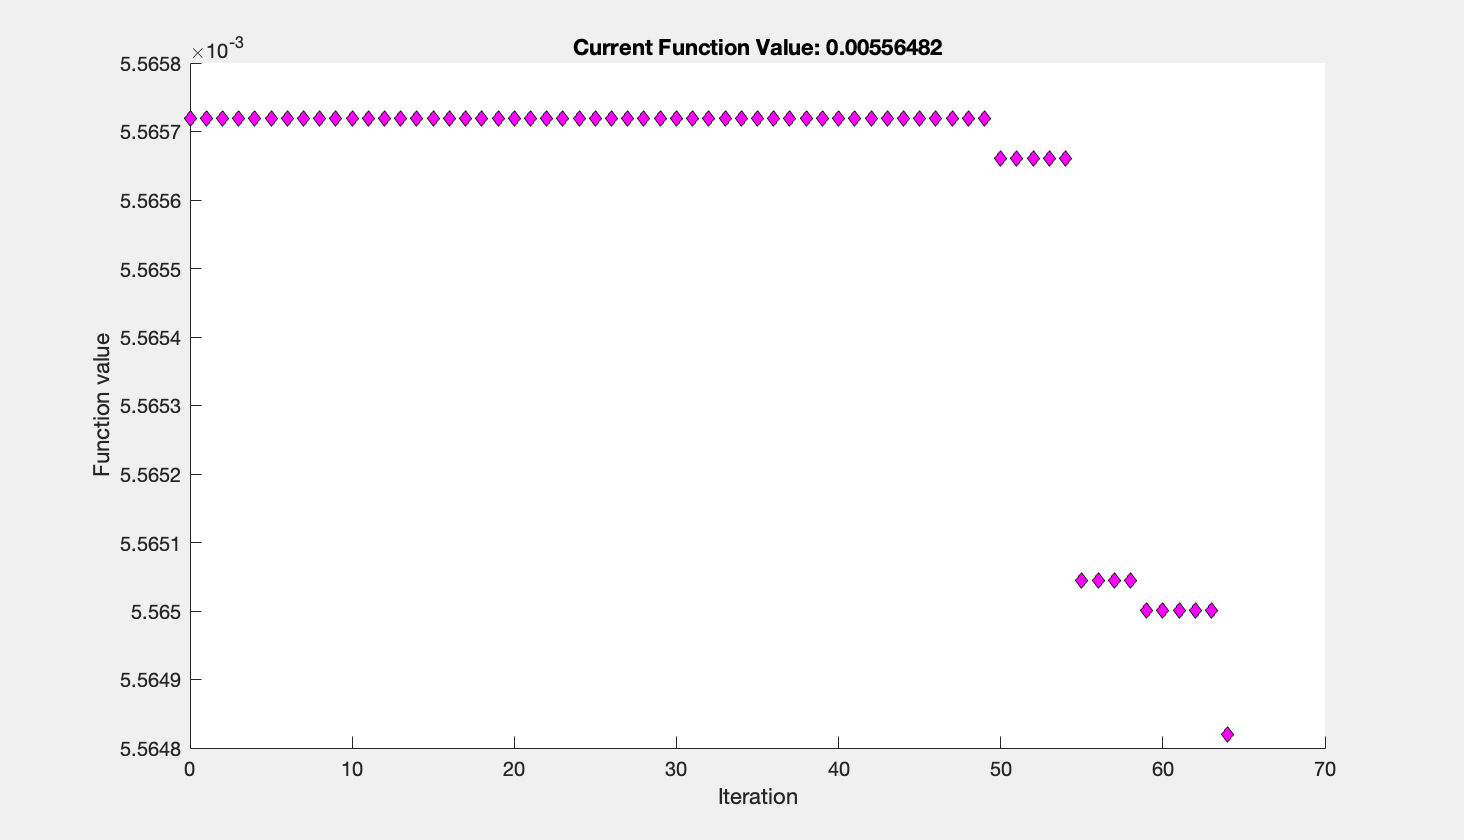

    0.0056



diff = 1;
while diff > 10E-4
    old_fval = fval2;
    [bp2, fval2] = best_param2(bp2,dpi,y,ti,init,h) ;
    diff = abs(fval2-old_fval);
    disp(fval2)
end

array2table(10.^bp2)

ans = 1×7 table
       Var1          Var2        Var3      Var4      Var5       Var6       Var7 
    __________    __________    ______    _______    _____    ________    ______

    4.6888e-07    2.2256e-07    1.0215    0.87775    17303    0.031234    4.4783


array2table(bp)

ans = 1×7 table
       bp1           bp2         bp3      bp4       bp5       bp6        bp7  
    __________    __________    _____    ______    _____    ________    ______

    3.4497e-07    1.5821e-07    1.486    1.2266    29104    0.036181    3.8412


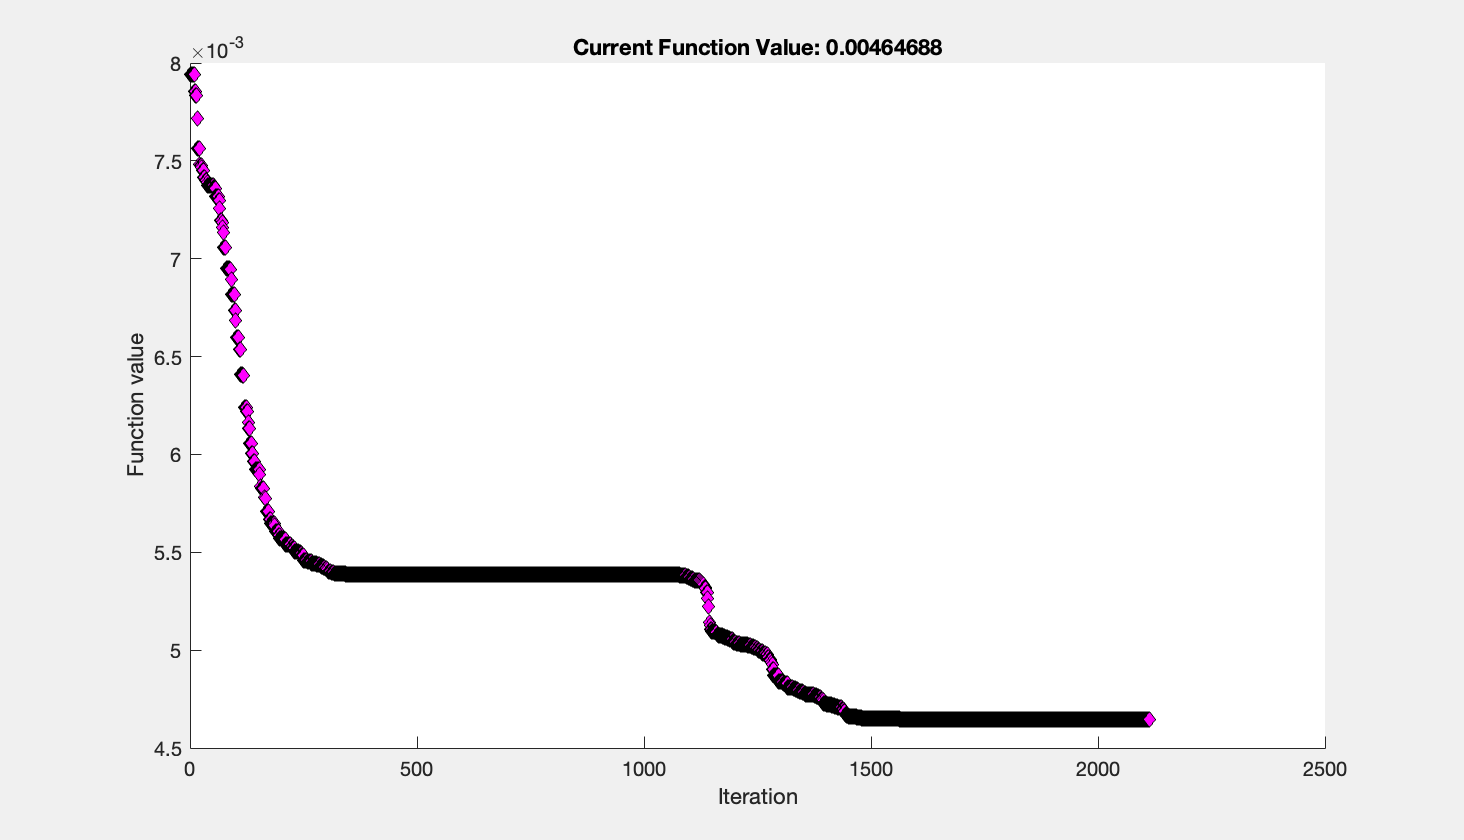

[bp, fval] = best_param(x0,dpi,y,ti,init,h) ;

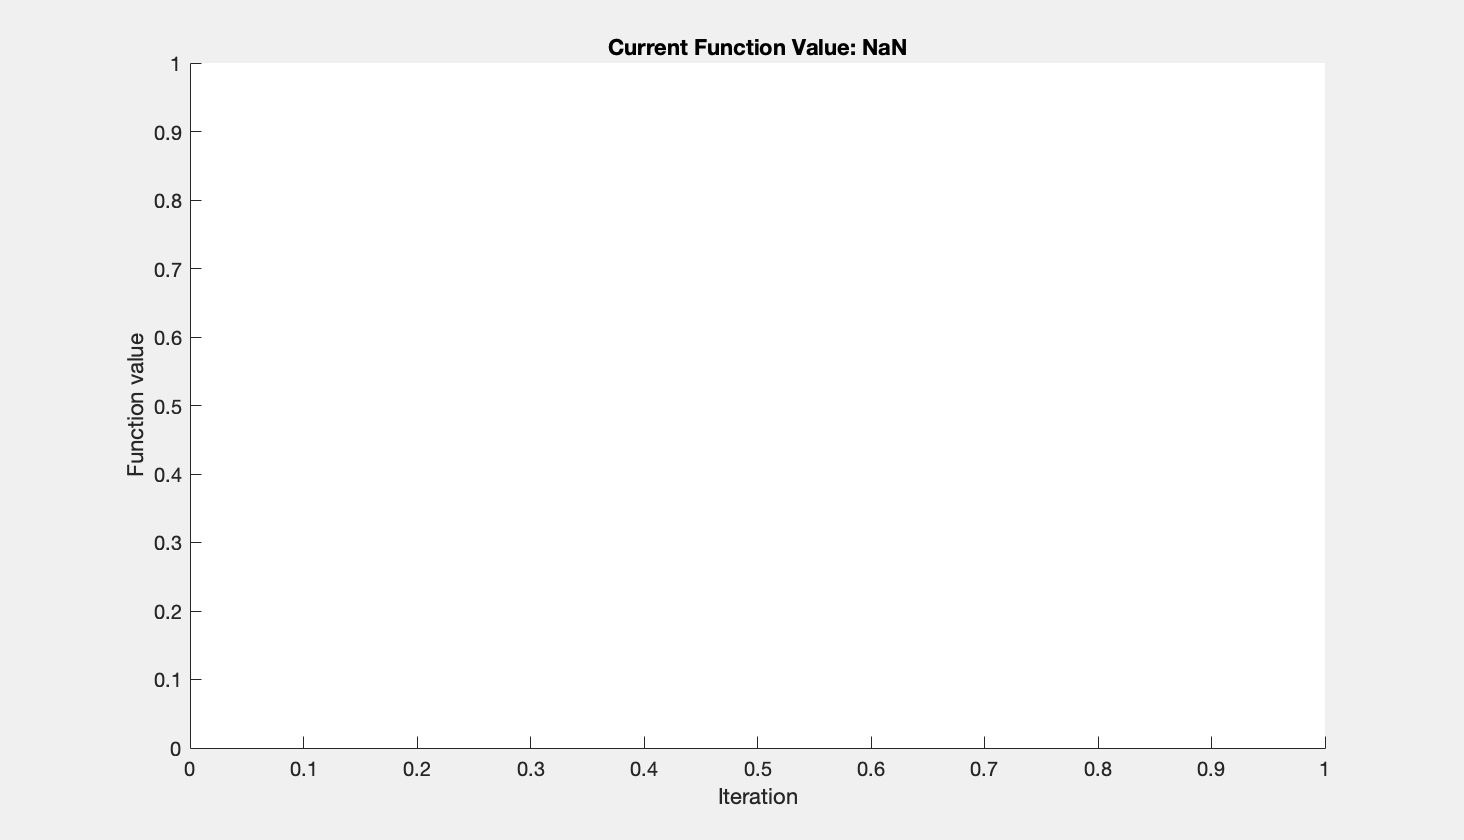

Optimization terminated prematurely by user.


    0.0046



diff = 1;
while diff > 10E-4
    old_fval = fval;
    [bp2, fval2] = best_param2(bp,dpi,y,ti,init,h) ;
    diff = abs(fval-old_fval);
    disp(fval)
end

array2table(bp2)

ans = 1×7 table
     bp21       bp22        bp23        bp24        bp25      bp26       bp27  
    _______    _______    ________    _________    ______    _______    _______

    -6.3871    -6.6248    -0.50143    -0.094771    4.1795    -1.5212    0.81335


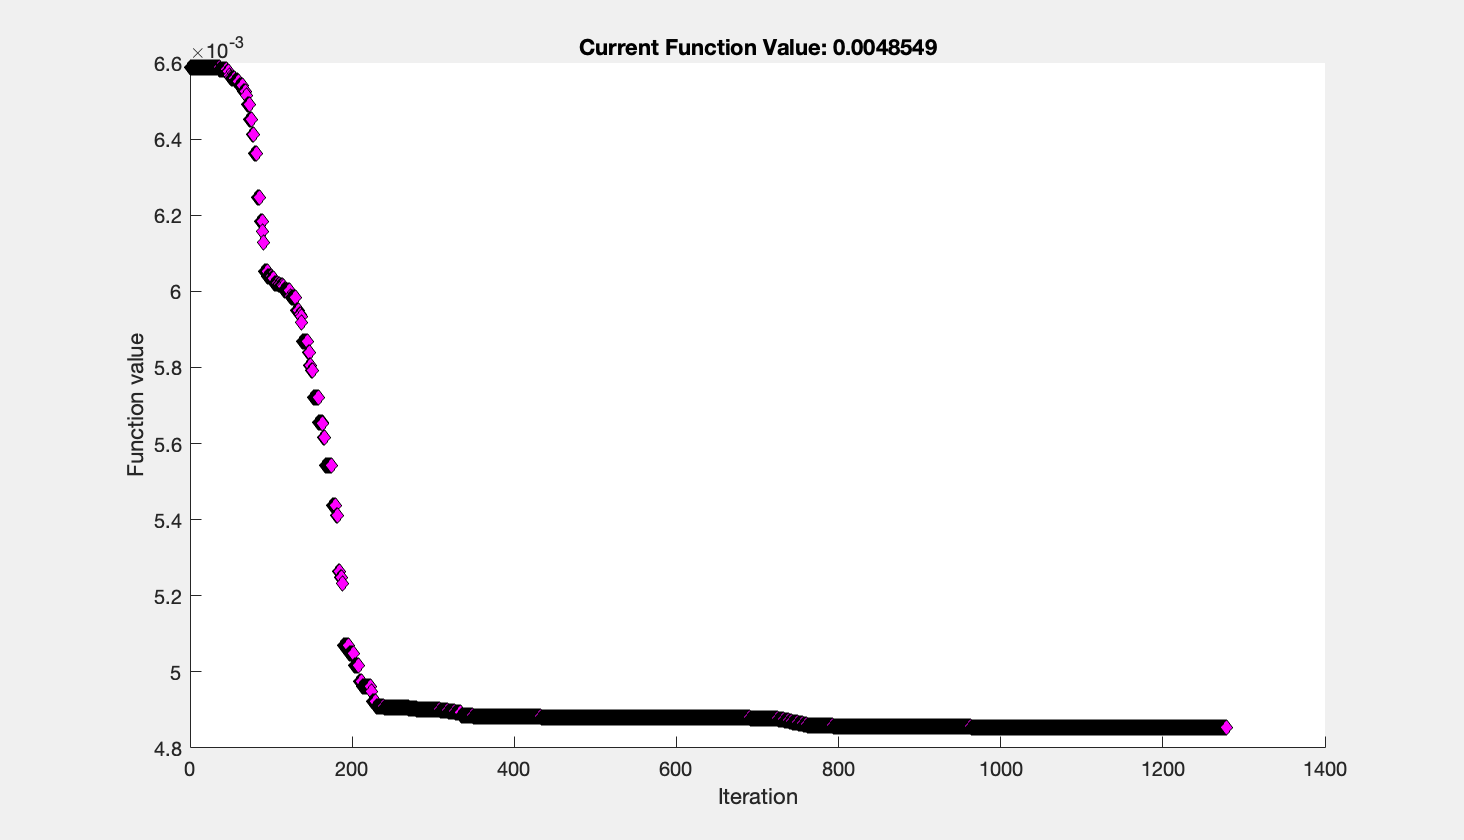

ans =    -6.4464   -6.7421    0.1749    0.0287    4.3713   -1.4659    0.7090



best_param2(bp2,dpi,y,ti,init,h)

ans = 1×7 table
    Var1    Var2    Var3      Var4     Var5      Var6       Var7 
    ____    ____    _____    ______    _____    _______    ______

     0       0      1.486    1.2266    29104    0.03618    3.8412


a= round(log10(bp),5);
v = 10.^a

v = 1.0e+04 *

    0.0000    0.0000    0.0001    0.0001    2.9104    0.0000    0.0004


v(1)

ans = 3.4497e-07

v(2)

ans = 1.5821e-07

v(3)

ans = 1.4860


for i = 1:7
    diff = bp(i)- v(i)
    disp(diff)
    if bp(i) == v(i)
%         disp([bp(i) v(i)] )
        disp(i)
    end
end 

diff = -5.5392e-13

  -5.5392e-13



diff = -8.7481e-13

  -8.7481e-13



diff = -8.7603e-06

  -8.7603e-06



diff = 8.3070e-07

   8.3070e-07



diff = 0.1916

    0.1916



diff = -4.1082e-07

  -4.1082e-07



diff = 3.9291e-05

   3.9291e-05



array2table(bp)

ans = 1×7 table
       bp1           bp2         bp3      bp4       bp5       bp6        bp7  
    __________    __________    _____    ______    _____    ________    ______

    3.4497e-07    1.5821e-07    1.486    1.2266    29104    0.036181    3.8412


array2table(10.^log10(bp))

ans = 1×7 table
       Var1          Var2       Var3      Var4     Var5       Var6       Var7 
    __________    __________    _____    ______    _____    ________    ______

    3.4497e-07    1.5821e-07    1.486    1.2266    29104    0.036181    3.8412



array2table(log10(bp))

ans = 1×7 table
     Var1       Var2       Var3       Var4      Var5      Var6       Var7  
    _______    _______    _______    _______    _____    _______    _______

    -6.4622    -6.8008    0.17203    0.08869    4.464    -1.4415    0.58446


array2table(bp2)

ans = 1×7 table
     bp21       bp22        bp23        bp24        bp25      bp26       bp27  
    _______    _______    ________    _________    ______    _______    _______

    -6.3871    -6.6248    -0.50143    -0.094769    4.1795    -1.5212    0.81335


J(10.^bp2, ti, init, h, dpi, y)

ans = 0.0066

J2(bp2, ti, init, h, dpi, y)

ans = 0.0066


J(bp, ti, init, h, dpi, y)

ans = 0.0046


J(10.^log10(bp), ti, init, h, dpi, y)

ans = 0.0047

J2(log10(bp), ti, init, h, dpi, y)

ans = 0.0047

function out=b(t,b0,bi,k,tau)
    if t <= tau
        out = b0;
    else
        out = bi+(b0-bi)*exp(-k*(t-tau));
    end
end


function out=J(params, ti,init,h, dpi,y)

    b0 = params(1);
    bi = params(2);
    k = params(3);
    dlt = params(4);
    p = params(5);
    d = params(6);
    tau = params(7);


    f = @(t,x) [d*(init(1)-x(1))-b(t,b0,bi,k,tau)*x(1)*x(3);...
            b(t,b0,bi,k,tau)*x(1)*x(3)-dlt*x(2);...
            p*x(2)-23*x(3) ];    

    [t,xa] = ode45(f,ti,init);
    V = xa(:,3);

    y_hat = log10(V(dpi/h+1));
    out =  1/size(y,1) *sum((y-y_hat).^2);
end 

function [x,fval]=best_param(x0,dpi,y,ti,init,h)
    options = optimset('PlotFcns','optimplotfval','TolFun',1e-7,'TolX',1e-7,'MaxFunEvals', 5000,'MaxIter', 5000);
    JJ = @(params) J(params, ti,init,h, dpi,y); 
    [x,fval] = fminsearch(JJ,x0,options);
end 

function out=b2(t,b0,bi,k,tau)
    if t <= 10^tau
        out = 10^b0;
    else
        out = 10^bi+(10^b0-10^bi)*exp(-10^k*(t-10^tau));
    end
end


function out=J2(params, ti,init,h, dpi,y)

    b0 = params(1);
    bi = params(2);
    k = params(3);
    dlt = params(4);
    p = params(5);
    d = params(6);
    tau = params(7);


    f = @(t,x) [10^d*(init(1)-x(1))-b2(t,b0,bi,k,tau)*x(1)*x(3);...
            b2(t,b0,bi,k,tau)*x(1)*x(3)-10^dlt*x(2);...
            10^p*x(2)-23*x(3) ];    

    [t,xa] = ode45(f,ti,init);
    V = xa(:,3);

    y_hat = log10(V(dpi/h+1));
    out =  1/size(y,1) *sum((y-y_hat).^2);
end 

function [x,fval]=best_param2(x0,dpi,y,ti,init,h)
    options = optimset('PlotFcns','optimplotfval','TolFun',1e-14,'TolX',1e-14,'MaxFunEvals', 5000,'MaxIter', 5000);
    JJ = @(params) J2(params, ti,init,h, dpi,y); 
    [x,fval] = fminsearch(JJ,x0,options);
end 


% function out=b3(t,b0,bi,k,tau)
%     if t <= 10^tau
%         out = 10^b0;
%     else
%         out = 10^bi+(10^b0-10^bi)*exp(-k*(t-tau));
%     end
% end
% 
% 
% function out=J3(params, ti,init,h, dpi,y)
% 
%     b0 = params(1);
%     bi = params(2);
%     k = params(3);
%     dlt = params(4);
%     p = params(5);
%     d = params(6);
%     tau = params(7);
% 
% 
%     f = @(t,x) [10^d*(init(1)-x(1))-b3(t,b0,bi,k,tau)*x(1)*x(3);...
%             b3(t,b0,bi,k,tau)*x(1)*x(3)-dlt*x(2);...
%             10^p*x(2)-23*x(3) ];    
% 
%     [t,xa] = ode45(f,ti,init);
%     V = xa(:,3);
% 
%     y_hat = log10(V(dpi/h+1));
%     out =  1/size(y,1) *sum((y-y_hat).^2);
% end 
% 
% function [x,fval]=best_param3(x0,dpi,y,ti,init,h)
%     options = optimset('PlotFcns','optimplotfval','TolFun',1e-14,'TolX',1e-14,'MaxFunEvals', 5000,'MaxIter', 5000);
%     JJ = @(params) J3(params, ti,init,h, dpi,y); 
%     [x,fval] = fminsearch(JJ,x0,options);
% end 

